%     Data Science (Prof. Neff)                Versuchsdatum 21.11.2020
%     Versuch Konfidenzintervalle
%     Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),
%     Anna Kuhn (2051063), Michael Schulze (2061282)
%     
%     Rohdaten der einzelnen Gruppenmitglieder


% Aufgabe 1
%Büroklammern
data_buero = readtable('Lebensdauer_Bueroklammer (1).csv')

data_buero = 75×1 table
    Zyklen
    ______

     9    
    61    
     3    
     2    
     4    
     7    
    25    
    16    
    97    
     4    
     5    
    50    
     2    
     2    
    13    
    17    



% Bueroklammern b)
pd_norm_buero = fitdist(data_buero.Zyklen,'Normal')

pd_norm_buero =   NormalDistribution

  Normal distribution
       mu = 15.6133   [10.6343, 20.5924]
    sigma = 21.6407   [18.6461, 25.7903]


ci_normal=paramci(pd_norm_buero,'Alpha',0.05)

ci_normal =    10.6343   18.6461
   20.5924   25.7903



[~,~,t_ci_buero,t_stats_buero] = ttest(data_buero.Zyklen)

t_ci_buero =    10.6343
   20.5924


t_stats_buero = struct with fields:
    tstat: 6.2482
       df: 74
       sd: 21.6407



pd_wybul_buero = fitdist(data_buero.Zyklen, 'Weibull')

pd_wybul_buero =   WeibullDistribution

  Weibull distribution
    A =  15.2792   [11.8995, 19.6187]
    B = 0.960767   [0.820185, 1.12545]


ci_weibull = paramci(pd_wybul_buero,'Alpha',0.05)

ci_weibull =    11.8995    0.8202
   19.6187    1.1254



[boot_buero, data_boot_buero]=bootstrp(10,@median,data_buero.Zyklen)

boot_buero =      9
     9
    11
    12
    13
    12
    11
    11
    12
    10


data_boot_buero =     38     6    41    30    49    13     1    49    64     7
    10    26    60    44    73    69    25    66    37     9
    35    75    68    23    51    74    26    37    42    75
    70    27    66    56    60    19     5    14     1    47
    41    36    45    70    31    72    70    27    75    21
    64    40    24    74    27    54    45    33     3    19
    20    65     4     2    23    70    54    46    15    57
     5    39    31    69    62    18    55    44    34    26
    46    71    10    31    40    48     5    38    19    55
    25    71    14    49    16    46    58    19    50    58


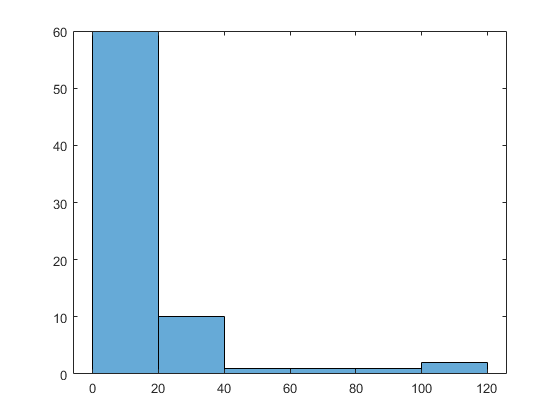


figure(2)
histogram(data_buero.Zyklen)

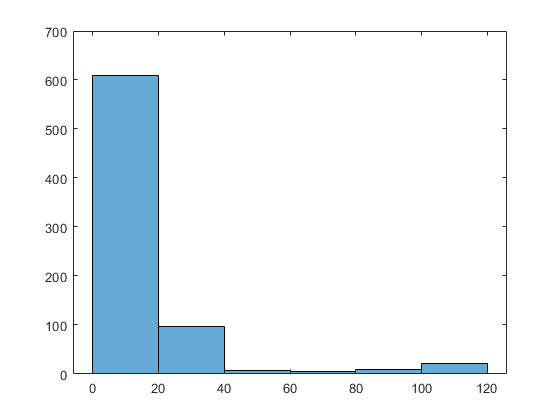


histogram(data_buero.Zyklen(data_boot_buero),6)


% Wasser MSA1 b)
data_msa = readtable('MSA_Verfahren1_200ml_Jan.csv')

data_msa = 25×1 table
    Gewicht_in_g
    ____________

    199         
    213         
    185         
    198         
    205         
    191         
    184         
    193         
    199         
    206         
    207         
    210         
    213         
    197         
    205         
    203         



pd_norm_msa = fitdist(data_msa.Gewicht_in_g, 'Normal')

pd_norm_msa =   NormalDistribution

  Normal distribution
       mu =  200.04   [196.787, 203.293]
    sigma = 7.88184   [6.15436, 10.9648]


ci_normal_msa = paramci(pd_norm_msa, 'Alpha', 0.05)

ci_normal_msa =   196.7865    6.1544
  203.2935   10.9648



[~,~,t_ci_msa,t_stats_msa] = ttest(data_msa.Gewicht_in_g)

t_ci_msa =   196.7865
  203.2935


t_stats_msa = struct with fields:
    tstat: 126.8994
       df: 24
       sd: 7.8818



pd_wybul_msa = fitdist(data_msa.Gewicht_in_g,'Weibull')

pd_wybul_msa =   WeibullDistribution

  Weibull distribution
    A =  203.71   [200.821, 206.64]
    B = 29.0413   [21.4884, 39.2491]


ci_wybul_msa = paramci(pd_wybul_msa, 'Alpha', 0.05)

ci_wybul_msa =   200.8207   21.4884
  206.6400   39.2491



[boot_msa, data_boot_msa]=bootstrp(1000,@median,data_msa.Gewicht_in_g)

boot_msa =    205
   198
   203
   204
   199
   197
   199
   205
   197
   203


data_boot_msa =      8    12     3     5     2     5    23    10     3     7    12     5    21    15     4    12    24    12     4    10     2    11     6    22    18     6     1     7    13     8    21    16     9    22    12     8     5     8     6    16    24    24    18    24    10     1    10    15    13     3
     2     9    11    20    16    13     4    25    19    11     7    12    15     2    20     3    18    13     9    18    24    22     8    20    11    14    15    21     9    14    12    25    22     5     3     5     5     7    22    12    19    19     6    21    14     8    25    19     6     8
    13    12     9    10    20    23     3    25    14    11     7    16    15    18     9    18    19    25     2    14    10    18     7    18     7    22    19    10     1     7     6    23    18    24     7     3    21     5    22     5     8     9    16     9     8    23    19    20     9    19
    25     2     7    22     3    21     7     9    19     6    22     1     7   

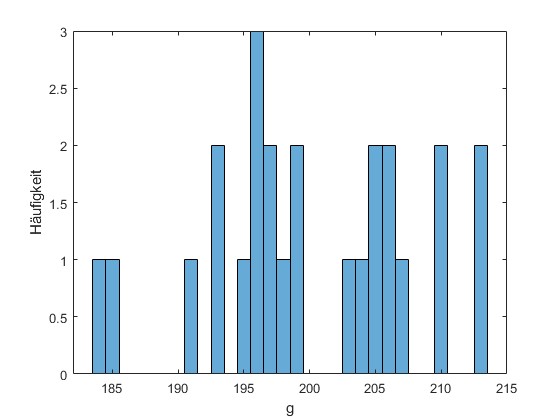



histogram(data_msa.Gewicht_in_g)
xlabel("g")
ylabel("Häufigkeit")

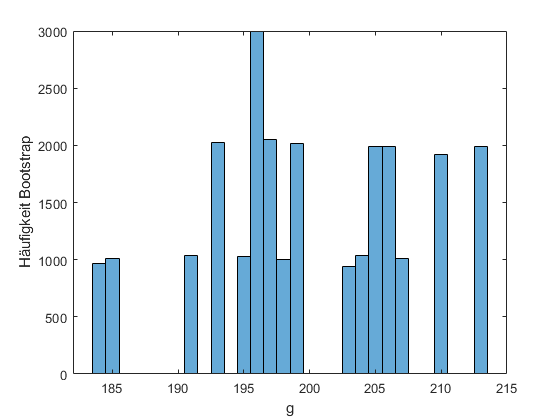

histogram(data_msa.Gewicht_in_g(data_boot_msa))
xlabel("g")
ylabel("Häufigkeit Bootstrap")

% Aufgabe 2
% Medikament hat keine Auswirkung auf Cholesterin
data_cholesterin_senker = readtable('cholesterinsenker.csv')

data_cholesterin_senker = 10×2 table
     A      B 
    ___    ___

      0    -22
    -27    -14
    -16    -15
    -13    -32
     -6    -22
    -27    -34
     -5    -38
    -22    -16
     -9    -25
     -3    -26


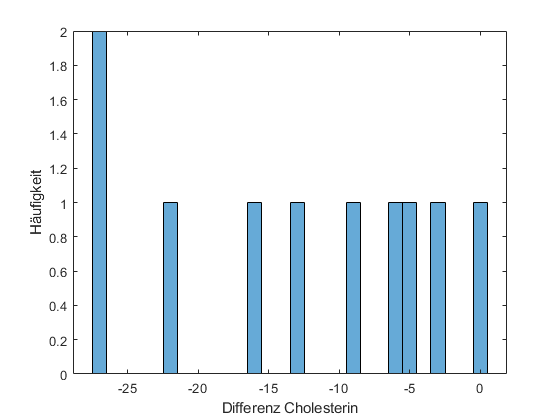


histogram(data_cholesterin_senker.A)
xlabel("Differenz Cholesterin")
ylabel("Häufigkeit")

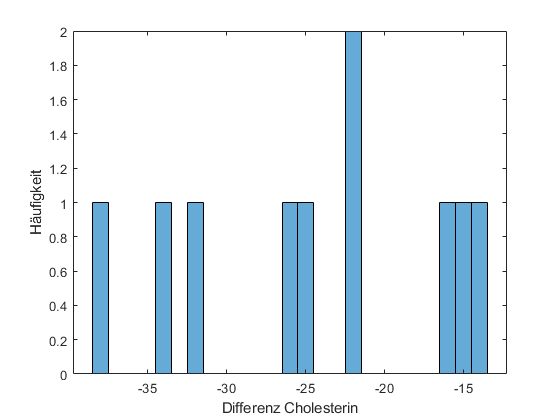


histogram(data_cholesterin_senker.B)
xlabel("Differenz Cholesterin")
ylabel("Häufigkeit")

%t-Test
data_cholesterin_senker = readtable('cholesterinsenker.csv')

data_cholesterin_senker = 10×2 table
     A      B 
    ___    ___

      0    -22
    -27    -14
    -16    -15
    -13    -32
     -6    -22
    -27    -34
     -5    -38
    -22    -16
     -9    -25
     -3    -26


fprintf("A erster Parameter")

A erster Parameter

[h0_ttest,p_ttest,ci_ttest,stats_ttest]=ttest2(data_cholesterin_senker.A,data_cholesterin_senker.B, 'alpha',0.01)

h0_ttest = 0

p_ttest = 0.0107

ci_ttest =    -0.1355
   23.3355


stats_ttest = struct with fields:
    tstat: 2.8452
       df: 18
       sd: 9.1165


%1: h0 ablehnen, 0: h0 nicht ablehnen = beibehalten

%verteilungsfreien Test auf Median:
[h0_rank,p_rank,stats_rank]=ranksum(data_cholesterin_senker.A,data_cholesterin_senker.B, 'alpha',0.01)

h0_rank = 0.0280

p_rank = logical
   0


stats_rank = struct with fields:
       zval: 2.1972
    ranksum: 134.5000


% 2e) Anderson_Darling_Test
[h0_adA, p_adA, ci_adA, stats_adA] = adtest(data_cholesterin_senker.A,'Alpha',0.01)

h0_adA = logical
   0


p_adA = 0.4677

ci_adA = 0.3289

stats_adA = 0.9339

[h0_adB, p_adB, ci_adB, stats_adB] = adtest(data_cholesterin_senker.B,'Alpha',0.01)

h0_adB = logical
   0


p_adB = 0.6616

ci_adB = 0.2635

stats_adB = 0.9339


%Verteilungsunabhängige Konfidenzintervalle für Quantile
%Berechnung des Konfidenzintervalls für den Median (McGill 1978)
% ci_lower=median()-1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)
% ci_upper=median(data)+1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)
% ci_median=[ci_lower,ci_upper]

%Veranschaulichung der Verteilung incl. Konfidenzintervall vom Median im
%Boxplot (Matlab verwendet obige Formel)
pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


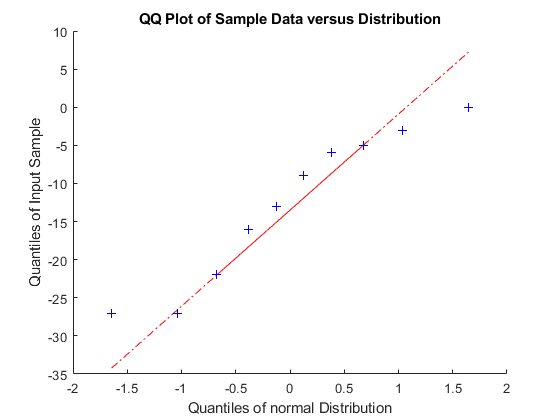

qqplot(data_cholesterin_senker.A,pd)

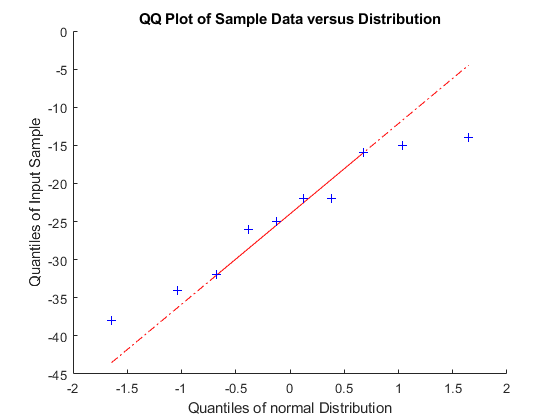

qqplot(data_cholesterin_senker.B,pd)